close all;
clear all;

%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]

forcing_amp   = data(:, 1);  % dependent variable (what we predict)
forcing_freq  = data(:, 2);  % input
response_amp  = data(:, 3);  % input

%% Generate Prediction Grid
% resp_range = linspace(min(response_amp), max(response_amp), 50);
resp_range = linspace(min(response_amp), 1.7, 50);
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
[RR, FF] = meshgrid(resp_range, freq_range);  % RR: response amp, FF: forcing freq

% Predict forcing amplitude
X_query = [RR(:), FF(:)];  % input = [response_amp, forcing_freq]



% training data set
init_data_num = 1;
training_idx = randperm(size(data, 1), init_data_num);





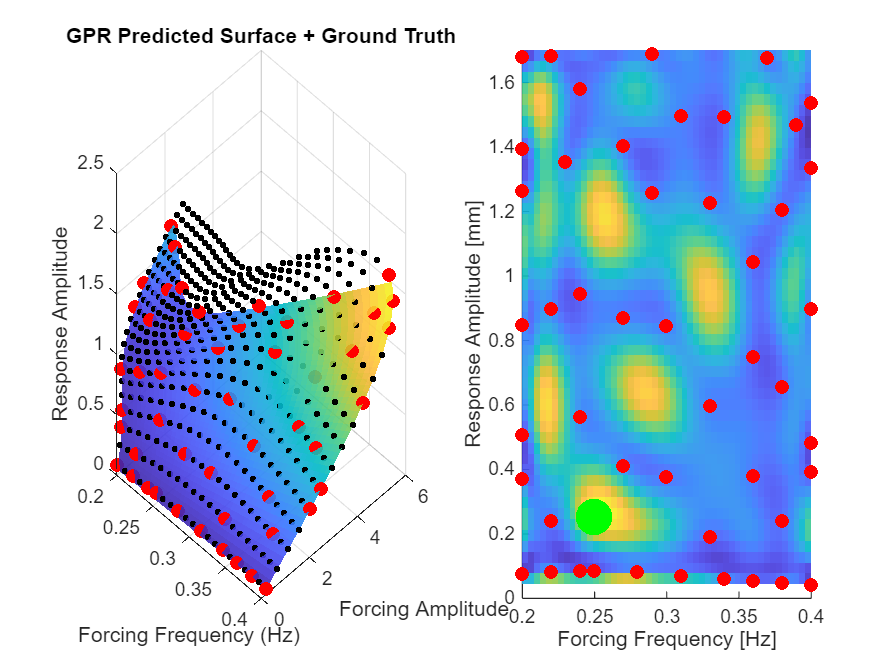

for i = (1:1)
    % pause(1)
    % train dataset
    input_data = data(training_idx, [3, 2]); % [response_amp, forcing_freq]
    output_data = data(training_idx, 1); % forcing_amp
    gpr_model = fitrgp(input_data, output_data, ...
        'KernelFunction', 'ardsquaredexponential', ...
        'Standardize', true);
    
    % query model
    [Y_pred, Y_std] = predict(gpr_model, X_query);
    AA = reshape(Y_pred, size(RR));     % Forcing amp surface
    STD = reshape(Y_std, size(RR));     % Confidence surface
    
    % select next test point
    [val, idx] = max(STD, [], "all");
    x_desired = [FF(idx), RR(idx)];
    x_possible = data(:, 2:3); %'data' = [forcing_amp, forcing_freq, response_amp]
    x_ranges = max(x_possible) - min(x_possible);
    x_norm = @(vec) (vec - min(x_possible))./x_ranges;
    [~, x_index] = min(sum((x_norm(x_possible) - x_norm(x_desired)).^2, 2));
    training_idx = [training_idx, x_index];
    
    
    %PLOTTING
    % Plot Surface with Points
    tiledlayout(1, 2, "TileSpacing","compact")
    nexttile;
    hold on;
    
    % Plot GPR surface
    surf(FF, AA, RR, AA, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
    scatter3(forcing_freq, forcing_amp, response_amp, 10, 'k', 'filled');
    scatter3(input_data(:, 2), output_data, input_data(:, 1), 40, 'r', 'filled');
    
    xlabel('Forcing Frequency (Hz)');
    ylabel('Forcing Amplitude');
    zlabel('Response Amplitude');
    % zlim([0, 1.7])
    title('GPR Predicted Surface + Ground Truth');
    view(45, 30);
    grid on;
    
    nexttile % plot variance
    hold on;
    surf(FF, ones(size(AA)).*6, RR, STD, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
    scatter3(data(x_index, 2), data(x_index, 1), data(x_index, 3), 50, "green", "LineWidth",10)
    scatter3(input_data(:, 2), output_data, input_data(:, 1), 40, 'r', 'filled');
    zlim([0, 1.7])
    xlabel("Forcing Frequency [Hz]");
    zlabel("Response Amplitude [mm]");
    view(0,0)
end

% --- 1) Extract trained GPR ingredients ---
gprMdl = gpr_model;

% === 1) Extract GPR internals ==========================================
X       = gprMdl.X;              % n×D training inputs
Y       = gprMdl.Y;              % n×1 targets
mu      = gprMdl.Beta;           % constant mean (if used)
theta   = gprMdl.KernelInformation.KernelParameters;  % [σ_f; ℓ₁…ℓ_D]
sigma2  = gprMdl.Sigma^2;         % noise variance

% Build K = K(X,X) + σ²I via our helper
K = se_kernel(X, X, theta) + sigma2*eye(size(X,1));
L = chol(K, 'lower');            % Cholesky factor

% Precompute alpha = K⁻¹ (Y − μ)
alpha = L'\( L\(Y - mu) );


% === 2) Analytic gradient at query points ==============================
% Xnew is M×D of query locations
Xnew = X_query;
[M, D] = size(Xnew);
grad   = zeros(M, D);

for i = 1:M
    % compute ∂k(X, x*)/∂x*  →  D×n
    dK = se_kernel_grad( X, Xnew(i,:), theta );
    % chain: ∇μ(x*) = (∂k/∂x*) * alpha
    grad(i,:) = (dK * alpha)';  
end

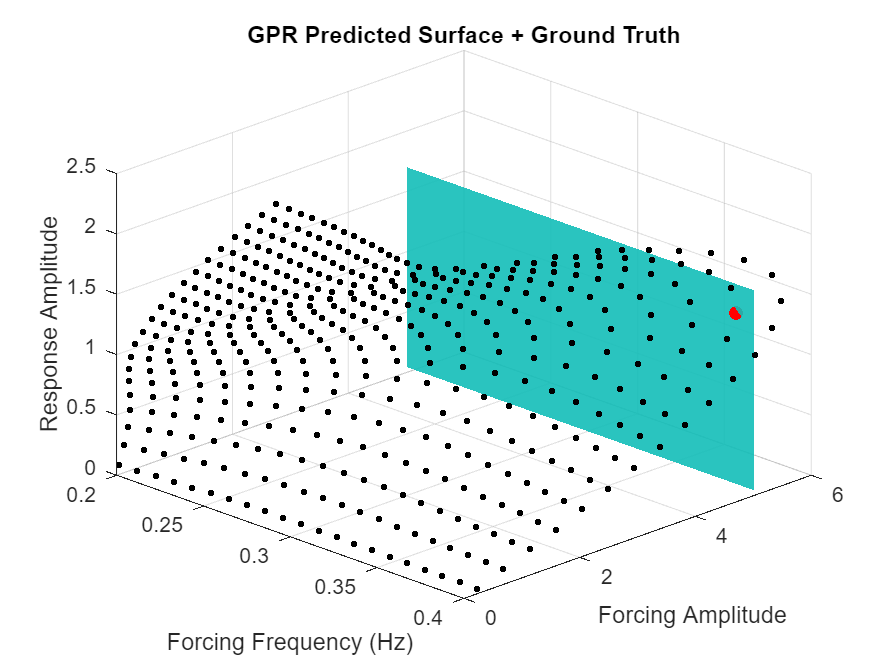

grad1 = reshape(grad(:, 1), size(RR));
grad2 = reshape(grad(:, 2), size(RR));

grad2d = sqrt(grad1.^2 + grad2.^2);

%PLOTTING
    % Plot Surface with Points
    % tiledlayout(1, 2, "TileSpacing","compact")
    % nexttile;
figure;
hold on;

% Plot GPR surface
surf(FF, AA, RR, grad1, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
scatter3(forcing_freq, forcing_amp, response_amp, 10, 'k', 'filled');
scatter3(input_data(:, 2), output_data, input_data(:, 1), 40, 'r', 'filled');

xlabel('Forcing Frequency (Hz)');
ylabel('Forcing Amplitude');
zlabel('Response Amplitude');
% zlim([0, 1.7])
title('GPR Predicted Surface + Ground Truth');
view(45, 30);
grid on;